# Task 1

## b) Deviation between the sideslip and crab angles

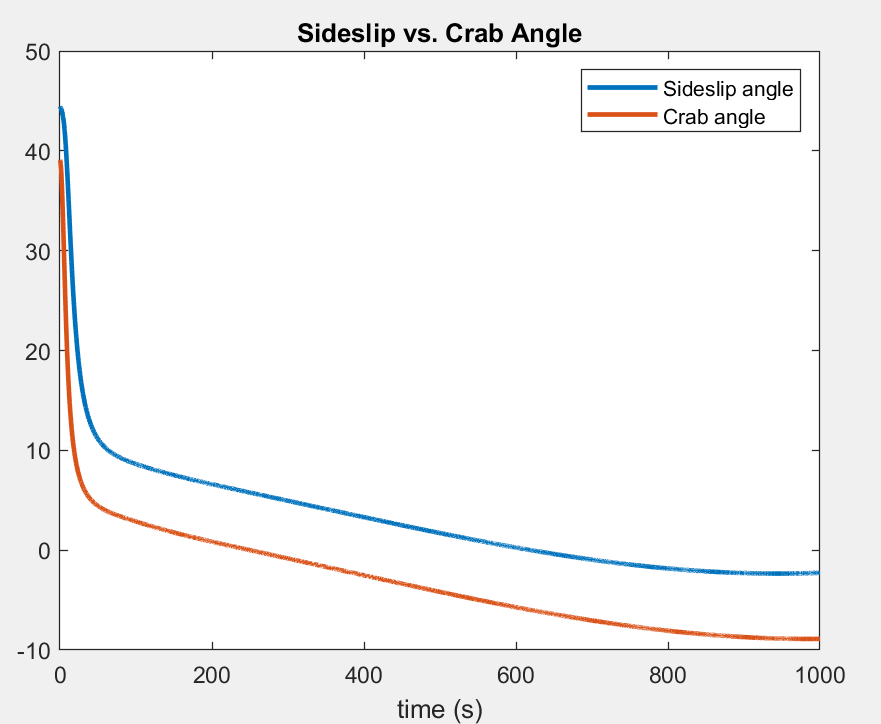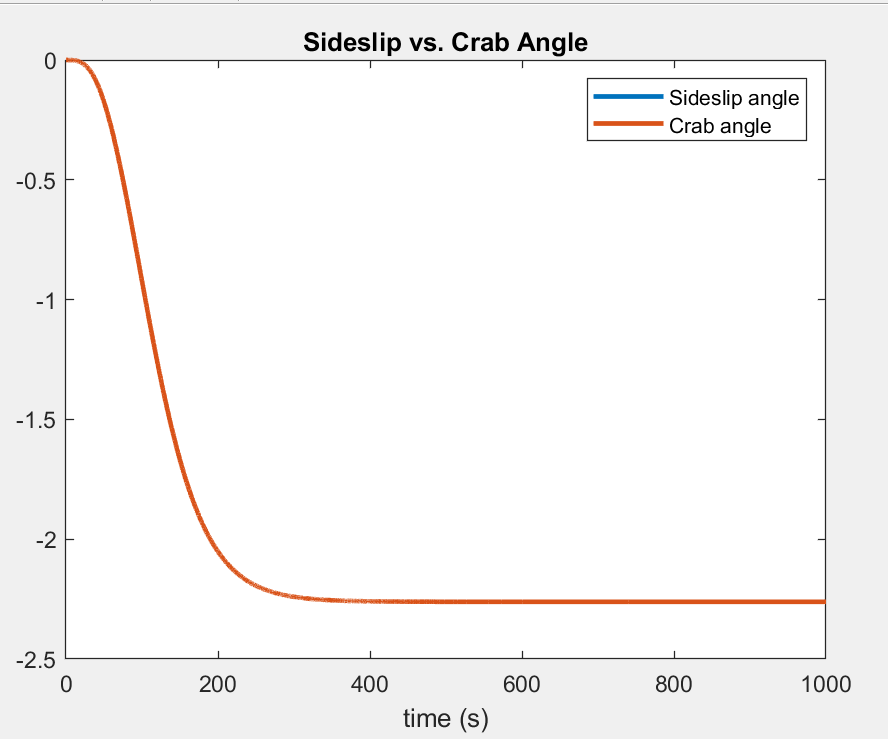

When there is no current (figure on the right), the sideslip and crab angles are identical. This follows from the definition of what the angles are. Sideslip angle relates the speed of the ship to the speed of the ocean currents while crab angle relates the speed to the ocean floor. When there is no current it follows that these angles are the same. 

We also observe that the sideslip angle converges to a lower value than when it started at $t=0$. This is because the ship speeds up and the speed of the ship will have a greater contribution to the angle than the small speed of the ocean current.

# Task 2

Parameters

clear; 

m = 17.0677e6;          % mass (kg)
Iz = 2.1732e10;         % yaw moment of inertia (kg m^2)
xg = -3.7;              % CG x-ccordinate (m)
L = 161;                % length (m)
B = 21.8;               % beam (m)
T = 8.9;                % draft (m)
rho = 1025;             % density of water (m/s^3)

Xudot = -8.9830e5;
Yvdot = -5.1996e6;
Yrdot =  9.3677e5;
Nvdot =  Yrdot;
Nrdot = -2.4283e10;

b = 2;
AR = 8;
CB = 0.8;

lambda = b^2 / AR;
tR = 0.45 - 0.28*CB;
CN = 6.13*lambda / (lambda + 2.25);
aH = 0.75;
xH = -0.4 * L;
xR = -0.5 * L;

t_thr = 0.05;                                        % thrust deduction number
X_delta2 = 0.5 * (1 - tR) * rho * AR * CN;           % rudder coefficients (Section 9.5)
Y_delta = 0.25 * (1 + aH) * rho * AR * CN; 
N_delta = 0.25 * (xR + aH*xH) * rho * AR * CN; 

M2dof = @(M3dof) (M3dof(2:3, 2:3)); 

## a) linearize the model

syms u v r

'syms' requires Symbolic Math Toolbox.

ud = 7; 
nu = [u; v; r]; 
nu0 = [ud; 0; 0];  % Replace ud with the desired value for u

% Linearize
CRB = m * nu(3,1) * [ 0 -1 -xg  
                    1  0  0 
                    xg 0  0  ]*nu; 
J_CRB = jacobian(CRB, nu)
J_CRB_linearized = double(subs(J_CRB, nu, nu0))
CA = [[0, 0, Yvdot*nu(2) + Yrdot*nu(3)]; 
      [0, 0, -Xudot*nu(1)]; 
      [-Yvdot*nu(2) - Yrdot*nu(3), Xudot*nu(1), 0]]*nu;  %eq 6.58

J_CA = jacobian(CA, nu) 
J_CA_linearized = double(subs(J_CA, nu, nu0))

## b) Transfer function delta to r

MA = -[ Xudot 0 0; 
        0 Yvdot Yrdot; 
        0 Nvdot Nrdot ];
MRB = [ m 0    0 
        0 m    m*xg
        0 m*xg Iz ];
T1 = 20; T2 = 20; T6 = 10;
Xu = -(m-Xudot)/T1;
Yv = -(m-Yvdot)/T2;
Nr = -(Iz-Nrdot)/T6;
D = -diag([Xu Yv Nr]);

M = MA + MRB; M = M2dof(M); Minv = inv(M) ; 
N = J_CA_linearized + J_CRB_linearized + D; N = M2dof(N); 
b = 2*ud*[Y_delta; N_delta]; 
C = [0, 1]; 
% Eq 6.138: M*nu_r_dot + N*nu_r = b*delta
% equivalent to nu_r_dot = -Minv*N*x + Min*b*delta
% We assume D = 0. 

[nom, denom] = ss2tf(-Minv*N, Minv*b, C, 0)

## c) First order Nomoto model. 

In order to find T and K, we write out the expression in eq 7.20, and equate the coefficients related to the same order. We must normalize the coefficients in the denominator in order to match the two transferfunctions. 

% Eq 7.20, 7.24, 7.25
K = nom(3)/denom(3)
% T3 = nom(2)*denom(3)/K 
% T1_pluss_T2 = denom(1)/denom(2)
% T = T1_pluss_T2 - T3  

T3 = sum(-1./roots(nom)) 
T1_pluss_T2 = sum(-1./roots(denom))

T = T1_pluss_T2 - T3

## d) Pole placement. See algorithm 15.1.

w_b = 0.06; 
zeta = 1; 
w_n = w_b/(sqrt(1 - 2 + sqrt(2))) 

kp = (w_n^2)*T/K 
kd = (2*w_n*T - 1)/K
ki = (w_n^3)*T/(10*K)

## e) Controller performance

We do not claim that integrator windup is a problem in oour simulations and so we ded not implement any ant-windup strategy.